Consultate la tabella DTMF al seguente link: https://it.wikipedia.org/wiki/Dual-tone_multi-frequency

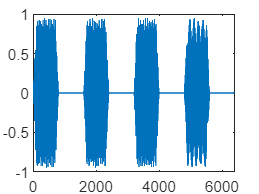

% La funzione audioread vi permette di leggere un file audio.
% Notate che y è il segnale e Fs la frequenza di campionamento
[y, Fs] = audioread('audio1.wav');

% Permette di riprodurre il suono.
sound(y, Fs)

% Visualizzare il segnale
plot(y)

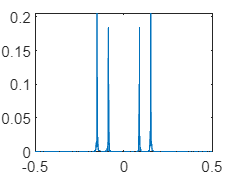


% Di fatto il segnale presentato è costuito da una sequenza di suoni
% intervallati da pause. Sia suoni sia pause durano 0.1 secondi, quindi
% possiamo considerare solo quella porzione di segnale che ci interessa per
% analizzare le frequenze del suono. Consideriamo il primo suono.
x = y(1:800);

% Calcoliamo la trasformata di Fourier ...
F = fftshift(fft(x));
freqNorm = linspace(-1/2, 1/2, numel(F));

% ... e visualizziamola
figure
plot(freqNorm, abs(F)/numel(F))

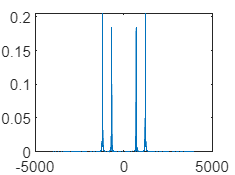


% Da frequenze normalizzata a quelle assolute (ricordiamo di moltiplicare
% per Fs). In questo modo possiamo effettivamente vedere in quale range di
% frequenze viene prodotto il suono e consultare la tabella per dire quale
% tasto è stato digitato.
freqNorm = Fs .* linspace(-1/2, 1/2, numel(F));

% Il tasto premuto è 1, infatti la frequenza più bassa ha valore attorno a
% 697 Hz e quella più alta valore attorno a 1209 Hz.
figure
plot(freqNorm, abs(F)/numel(F))